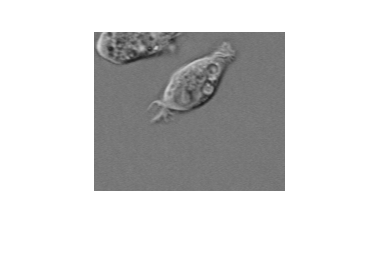

clear; clc;
cell = imread('cell.tif');
figure; imshow(cell)

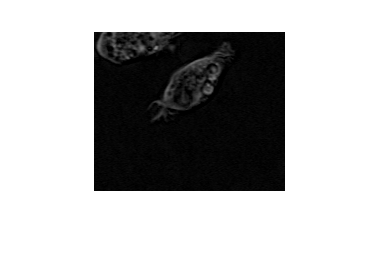

cell1 = imtophat(cell, strel('disk', 10)); % a morphological trans
figure; imshow(cell1)

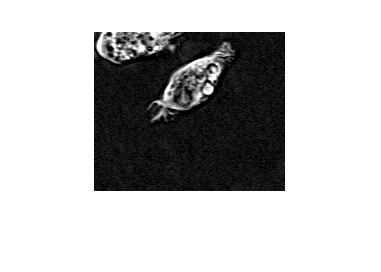

cell2 = imadjust(cell1);
figure; imshow(cell2)

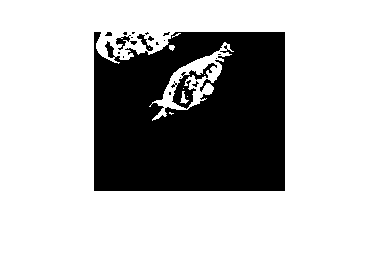

level = graythresh(cell2);
bw = im2bw(cell2, level);
figure; imshow(bw)

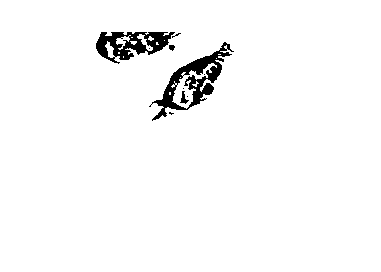

c = ~bw;
figure; imshow(c)

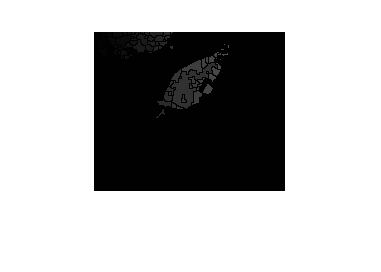

d = -bwdist(c);
d(c) = -inf;
l = watershed(d);
figure; imshow(l)

wi = label2rgb(l, 'hot', 'w');

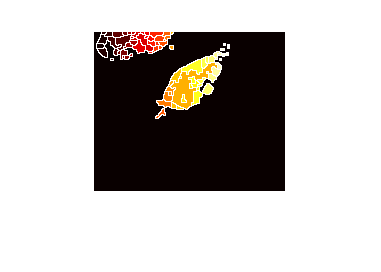

figure; imshow(wi)

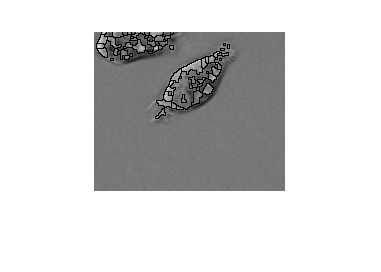

im = cell;
im(l == 0) = 0;
figure; imshow(im)